iters = 51;
init_iterations = [];
rnd_iterations = [];
for iter=1:iters
    iter
    dim = [iter+1,iter+1,iter+1];
    T = zeros(dim);
    for i = 1:size(T,1)
        T(i,:,:) = diag(randn(size(T,2),1));
    end
    %disp("{2,3} diagonal Tensor:");
    %disp(T);
    x = randn(dim(2),1);
    %disp("x:");
    %disp(x);
    b = tmprod(T,{x.',x.'},[2,3]);
    %disp("b:")
    %disp(b);
    xest = solve_part_diag(T,b);
    %disp("estimated x:");
    %disp(xest);
    %verifying solution given by the function 
    rerrx = frob(x-xest)/frob(x);
    best = tmprod(T,{xest.',xest.'},[2,3]);
    rerrb = frob(b-best)/frob(b) ;
    T0= [];
    for i=1:dim(2)
        T0 = [T0,xest];
    end
    
%     U0= cpd(T0,1);
    U0 = {xest,xest};
    [U,output] = lscpd_nls(T,b,U0);
    init_iterations = [init_iterations,output.iterations];
    U0 = cpd_rnd(dim(2:3),1);
    [U2,output2] = lscpd_nls(T,b,U0);
    rnd_iterations= [rnd_iterations,output2.iterations];
end

iter = 1

iter = 2

iter = 3

iter = 4

iter = 5

iter = 6

iter = 7

iter = 8

iter = 9

iter = 10

iter = 11

iter = 12

iter = 13

iter = 14

iter = 15

iter = 16

iter = 17

iter = 18

iter = 19

iter = 20

iter = 21

iter = 22

iter = 23

iter = 24

iter = 25

iter = 26

iter = 27

iter = 28

iter = 29

iter = 30

iter = 31

iter = 32

iter = 33

iter = 34

iter = 35

iter = 36

iter = 37

iter = 38

iter = 39

iter = 40

iter = 41

iter = 42

iter = 43

iter = 44

iter = 45

iter = 46

iter = 47

iter = 48

iter = 49

iter = 50

iter = 51

x = [2:iters+1]

x =      2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51


init_iterations

init_iterations =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


rnd_iterations

rnd_iterations =      4     7     9     4     7     8     9     7    11    10    11     7    11    10    10     8    10     7    10    10    11     7     7     9     9     7     9     8     8     8     7    10    11     9     8    10     9     8     8     9    11    11     8    11    10     9     8     9     7   144


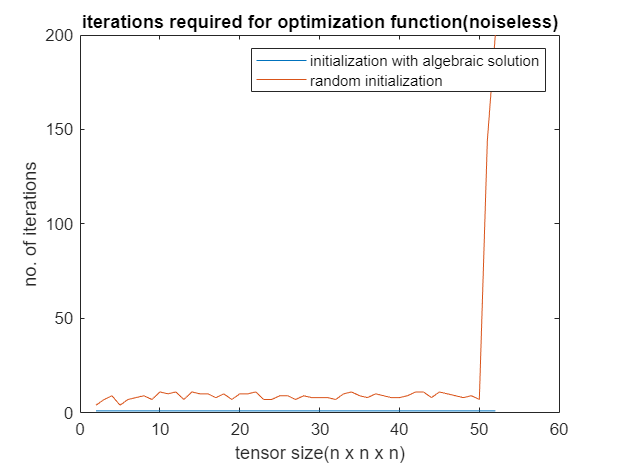

figure

plot(x,init_iterations,x,rnd_iterations)
title('iterations required for optimization function(noiseless)')
legend('initialization with algebraic solution','random initialization')
xlabel('tensor size(n x n x n)')
ylabel('no. of iterations')

output

output = struct with fields:
           alpha: []
    cgiterations: 25
        cgrelres: 0.0340
           delta: [3.1791 3.1791]
            fval: [2.0853e-27 3.4330e-28]
            info: 2
          infops: []
      iterations: 1
         relfval: 0.8354
         relstep: 4.2921e-15
             rho: 0.8618
          kernel: [1×1 LSCPD_Kernel]
      LargeScale: 1


output2

output2 = struct with fields:
           alpha: []
    cgiterations: [25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 25 … ]
        cgrelres: [0.0130 0.0451 0.0273 0.0309 0.0029 0.0267 0.0196 0.0130 0.0081 0.4750 0.0767 0.8894 0.9722 0.2565 1.1891 0.4614 0.8999 0.8965 0.6405 0.6274 1.4862 0.1861 2.0089 0.9326 0.4059 0.2270 4.0979 0.1543 7.9196 0.1431 6.2509 0.1377 4.6624 … ]
           delta: [2.7186 5.4372 10.8745 21.7489 13.4581 3.3645 6.7290 6.1362 12.2723 16.2851 16.2851 16.2851 16.2851 16.2851 16.2851 16.2851 16.2851 16.2851 16.2851 16.2851 16.2851 16.2851 16.2851 16.2851 16.2851 16.2851 16.2851 16.2851 16.2851 … ]
            fval: [3.7767e+03 2.0390e+03 1.0281e+03 480.6814 410.2881 133.1826 126.3013 56.6555 10.5566 0.1371 0.0617 0.0350 0.0264 0.0208 0.0181 0.0160 0.0144 0.0133 0.0124 0.0117 0.0110 0.0

iters = 5

iters = 5

for iter=1:iters
    dim = [iter+1,iter+1,iter+1];
    T = zeros(dim);
    for i = 1:size(T,1)
        T(i,:,:) = diag(randn(size(T,2),1));
    end
    %disp("{2,3} diagonal Tensor:");
    %disp(T);
    x = randn(dim(2),1);
    %disp("x:");
    %disp(x);
    b = tmprod(T,{x.',x.'},[2,3]);
    %disp("b:")
    %disp(b);
    xest = solve_part_diag(T,b);
    %disp("estimated x:");
    %disp(xest);
    %verifying solution given by the function 
    rerrx = frob(x-xest)/frob(x);
    best = tmprod(T,{xest.',xest.'},[2,3]);
    rerrb = frob(b-best)/frob(b) ;
    T0= [];
    for i=1:dim(2)
        T0 = [T0,x];
    end
    
    U0= cpd(T0,1);
    [U,output] = lscpd_nls(T,b,U0);
    output.fval
    U0 = cpd_rnd([dim(1),dim(2)],1);
    [U2,output2] = lscpd_nls(T,b,U0);
    output2.iterations
end

ans =     0.7671    0.0873    0.0501    0.0313    0.0226    0.0075    0.0000    0.0000    0.0000         0


ans = 5

ans =     4.3775    2.1738    0.6471    0.0940    0.0002    0.0000    0.0000    0.0000


ans = 8

ans =     2.1769    0.2474    0.0597    0.0483    0.0113    0.0019    0.0009    0.0000    0.0000    0.0000


ans = 6

ans =    60.8613    4.9374    0.9143    0.3094    0.0016    0.0000    0.0000    0.0000


ans = 8

ans =    56.5117   19.7799    0.8522    0.0931    0.0001    0.0000    0.0000    0.0000


ans = 10

Noise in the right hand side b, for {2,3} diagonal tensor

% SNRS = [0,10,20,30];
SNRS = [0,60,80,Inf];
iters = 100;

%% initialized exp_data %%
init_SNR_iters = [];
rnd_SNR_iters = [];
exp_data.iterations = [];
exp_data.type = [];
exp_data.SNR = [];
% exp_data.SNR = ones(1,iters*2)*SNRS(1);
% exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(2)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(3)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(4)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(5)];
options = struct;
options.TolFun = eps^2;
options.TolX = eps;
options.LargeScale = false;
%% -----------------   %%
for SNR=1:size(SNRS,2)
    init_iterations = [];
    rnd_iterations = [];
    for iter=1:iters
        it_data = struct;
        dim = [10,20,20];
        T = zeros(dim);
        for i = 1:size(T,1)
             T(i,:,:) = diag(randi([-100,100],size(T,2),1));
            %T(i,:,:) = diag(rand(size(T,2),1));
        end

        x = randi([-100,100],dim(2),1);
    
        b = tmprod(T,{x.',x.'},[2,3]);
        b_noisy = noisy(b,SNRS(SNR));
        T_noisy = noisy(T,SNRS(SNR));
        T_noisy_dup = zeros(size(T_noisy));
        for k = 1:size(T,1)
            T_noisy_dup(k,:,:) = diag(diag(squeeze(T_noisy(k,:,:))));
        end

        xest = solve_part_diag(T_noisy_dup,b);

        best = tmprod(T_noisy,{xest.',xest.'},[2,3]);
        rerrb = frob(b-best)/frob(b)
    
     
        U0 = {xest,xest};
        [U,output] = lscpd_nls(T_noisy,b,U0,options);
        output.iterations
        init_iterations = [init_iterations,output.iterations];
        cpderr(x,U{1});


        %%collecting data
        exp_data.iterations = [exp_data.iterations,output.iterations];
        exp_data.type = [exp_data.type,1];
        exp_data.SNR = [exp_data.SNR,SNRS(SNR)];
        %%--------------%%
        
      

        U0 = cpd_rnd(dim(2:3),1);
        [U2,output2] = lscpd_nls(T_noisy,b,U0,options);
        cpderr(x,U2{1});

        %%collecting data
        rnd_iterations= [rnd_iterations,output2.iterations];
        exp_data.iterations = [exp_data.iterations,output2.iterations];
        exp_data.type = [exp_data.type,0];
        exp_data.SNR = [exp_data.SNR,SNRS(SNR)];
        %%--------------%%
    end
    init_SNR_iters = [init_SNR_iters;init_iterations];
    rnd_SNR_iters = [rnd_SNR_iters;rnd_iterations];
end

rerrb = 0.3955

ans = 6

rerrb = 0.6780

ans = 7

rerrb = 0.4213

ans = 8

rerrb = 0.5343

ans = 8

rerrb = 0.5981

ans = 7

rerrb = 0.5408

ans = 8

rerrb = 1.0086

ans = 7

rerrb = 0.7516

ans = 6

rerrb = 0.8519

ans = 6

rerrb = 0.7810

ans = 8

rerrb = 0.5296

ans = 9

rerrb = 0.6320

ans = 7

rerrb = 0.5369

ans = 7

rerrb = 0.3086

ans = 7

rerrb = 0.6038

ans = 9

rerrb = 1.1266

ans = 8

rerrb = 0.5529

ans = 8

rerrb = 0.7241

ans = 8

rerrb = 0.5690

ans = 6

rerrb = 0.8316

ans = 6

rerrb = 0.3752

ans = 8

rerrb = 0.5934

ans = 8

rerrb = 0.6081

ans = 6

rerrb = 0.5155

ans = 6

rerrb = 0.5196

ans = 7

rerrb = 0.8769

ans = 8

rerrb = 0.6137

ans = 9

rerrb = 0.4746

ans = 7

rerrb = 0.8210

ans = 7

rerrb = 0.4827

ans = 9

rerrb = 0.6262

ans = 7

rerrb = 0.4779

ans = 8

rerrb = 0.4365

ans = 8

rerrb = 0.7458

ans = 8

rerrb = 0.8842

ans = 7

rerrb = 0.9271

ans = 7

rerrb = 0.6464

ans = 7

rerrb = 0.6229

ans = 8

rerrb = 1.2030

ans = 7

rerrb = 0.7498

ans = 7

rerrb = 0.7877

ans = 8

rerrb = 0.6270

ans = 7

rerrb = 1.9761

ans = 7

rerrb = 0.5930

ans = 8

rerrb = 0.7473

ans = 6

rerrb = 0.7369

ans = 9

rerrb = 0.5091

ans = 9

rerrb = 0.8188

ans = 7

rerrb = 0.7506

ans = 9

rerrb = 0.4928

ans = 7

rerrb = 0.3448

ans = 8

rerrb = 0.4637

ans = 8

rerrb = 0.3623

ans = 8

rerrb = 0.3693

ans = 6

rerrb = 0.5386

ans = 7

rerrb = 0.8964

ans = 7

rerrb = 0.7505

ans = 6

rerrb = 0.4698

ans = 8

rerrb = 0.5904

ans = 8

rerrb = 0.7703

ans = 7

rerrb = 0.6035

ans = 7

rerrb = 0.4043

ans = 6

rerrb = 0.6053

ans = 8

rerrb = 0.8879

ans = 8

rerrb = 0.7407

ans = 7

rerrb = 1.1716

ans = 7

rerrb = 0.7348

ans = 8

rerrb = 0.7133

ans = 8

rerrb = 0.2949

ans = 8

rerrb = 0.4513

ans = 6

rerrb = 0.4448

ans = 7

rerrb = 0.5190

ans = 7

rerrb = 1.1417

ans = 7

rerrb = 0.5240

ans = 7

rerrb = 0.8795

ans = 8

rerrb = 0.5908

ans = 8

rerrb = 0.4747

ans = 7

rerrb = 0.6057

ans = 8

rerrb = 0.4086

ans = 7

rerrb = 0.6063

ans = 7

rerrb = 0.5805

ans = 8

rerrb = 0.6332

ans = 7

rerrb = 0.5882

ans = 8

rerrb = 0.4336

ans = 8

rerrb = 0.5095

ans = 7

rerrb = 0.7377

ans = 7

rerrb = 0.9648

ans = 8

rerrb = 0.6333

ans = 6

rerrb = 0.7987

ans = 6

rerrb = 0.6835

ans = 7

rerrb = 0.4085

ans = 8

rerrb = 0.6286

ans = 8

rerrb = 0.6555

ans = 8

rerrb = 0.8149

ans = 6

rerrb = 0.5879

ans = 6

rerrb = 0.7240

ans = 6

rerrb = 0.4515

ans = 8

rerrb = 0.5758

ans = 7

rerrb = 0.4486

ans = 6

rerrb = 0.8433

ans = 7

rerrb = 4.3731e-04

ans = 5

rerrb = 8.0577e-04

ans = 4

rerrb = 3.4464e-04

ans = 5

rerrb = 4.5487e-04

ans = 4

rerrb = 8.1741e-04

ans = 5

rerrb = 9.8235e-04

ans = 5

rerrb = 7.5285e-04

ans = 5

rerrb = 5.8861e-04

ans = 5

rerrb = 2.8546e-04

ans = 6

rerrb = 6.5149e-04

ans = 5

rerrb = 4.6168e-04

ans = 7

rerrb = 5.6441e-04

ans = 6

rerrb = 0.0013

ans = 4

rerrb = 0.0010

ans = 5

rerrb = 6.9797e-04

ans = 5

rerrb = 6.6101e-04

ans = 5

rerrb = 4.7978e-04

ans = 6

rerrb = 6.8153e-04

ans = 5

rerrb = 6.9055e-04

ans = 4

rerrb = 4.8151e-04

ans = 5

rerrb = 6.4846e-04

ans = 5

rerrb = 8.2121e-04

ans = 5

rerrb = 5.8106e-04

ans = 5

rerrb = 4.4400e-04

ans = 5

rerrb = 5.8251e-04

ans = 6

rerrb = 4.0433e-04

ans = 4

rerrb = 3.6308e-04

ans = 6

rerrb = 6.9163e-04

ans = 5

rerrb = 2.8783e-04

ans = 7

rerrb = 4.3123e-04

ans = 5

rerrb = 3.0001e-04

ans = 6

rerrb = 7.2208e-04

ans = 5

rerrb = 5.3285e-04

ans = 5

rerrb = 7.4499e-04

ans = 4

rerrb = 4.9700e-04

ans = 7

rerrb = 6.7831e-04

ans = 5

rerrb = 7.6635e-04

ans = 5

rerrb = 7.6547e-04

ans = 5

rerrb = 5.3794e-04

ans = 4

rerrb = 4.8644e-04

ans = 5

rerrb = 5.3785e-04

ans = 4

rerrb = 5.5600e-04

ans = 4

rerrb = 4.9238e-04

ans = 5

rerrb = 0.0011

ans = 5

rerrb = 9.3950e-04

ans = 6

rerrb = 4.0358e-04

ans = 5

rerrb = 4.1817e-04

ans = 5

rerrb = 5.0318e-04

ans = 6

rerrb = 0.0012

ans = 4

rerrb = 3.4826e-04

ans = 5

rerrb = 7.8411e-04

ans = 5

rerrb = 5.6783e-04

ans = 5

rerrb = 5.7337e-04

ans = 5

rerrb = 3.8960e-04

ans = 4

rerrb = 3.9902e-04

ans = 5

rerrb = 5.6487e-04

ans = 5

rerrb = 6.2331e-04

ans = 6

rerrb = 4.6762e-04

ans = 5

rerrb = 9.9437e-04

ans = 6

rerrb = 4.8566e-04

ans = 5

rerrb = 3.3510e-04

ans = 5

rerrb = 7.0251e-04

ans = 5

rerrb = 7.4063e-04

ans = 7

rerrb = 8.9672e-04

ans = 4

rerrb = 8.6330e-04

ans = 5

rerrb = 6.9959e-04

ans = 6

rerrb = 0.0014

ans = 4

rerrb = 9.0292e-04

ans = 5

rerrb = 7.5574e-04

ans = 5

rerrb = 7.6784e-04

ans = 6

rerrb = 8.5480e-04

ans = 4

rerrb = 3.4617e-04

ans = 5

rerrb = 3.9420e-04

ans = 5

rerrb = 0.0011

ans = 5

rerrb = 5.8302e-04

ans = 6

rerrb = 5.8358e-04

ans = 7

rerrb = 7.0569e-04

ans = 6

rerrb = 4.7054e-04

ans = 6

rerrb = 7.9463e-04

ans = 5

rerrb = 5.1331e-04

ans = 5

rerrb = 6.8392e-04

ans = 5

rerrb = 7.7336e-04

ans = 6

rerrb = 4.4045e-04

ans = 6

rerrb = 8.0572e-04

ans = 5

rerrb = 5.9233e-04

ans = 4

rerrb = 4.9281e-04

ans = 6

rerrb = 6.2433e-04

ans = 5

rerrb = 5.5465e-04

ans = 5

rerrb = 0.0010

ans = 5

rerrb = 4.8091e-04

ans = 5

rerrb = 6.6847e-04

ans = 6

rerrb = 6.1616e-04

ans = 5

rerrb = 4.0726e-04

ans = 5

rerrb = 5.6883e-04

ans = 6

rerrb = 7.0129e-04

ans = 5

rerrb = 4.3925e-04

ans = 5

rerrb = 7.0548e-04

ans = 6

rerrb = 8.3378e-04

ans = 4

rerrb = 2.8359e-04

ans = 6

rerrb = 6.0289e-04

ans = 4

rerrb = 5.6211e-05

ans = 4

rerrb = 6.9022e-05

ans = 5

rerrb = 5.7550e-05

ans = 4

rerrb = 4.4600e-05

ans = 4

rerrb = 4.6129e-05

ans = 4

rerrb = 6.8085e-05

ans = 5

rerrb = 5.1141e-05

ans = 4

rerrb = 6.8479e-05

ans = 4

rerrb = 5.6943e-05

ans = 4

rerrb = 5.2528e-05

ans = 4

rerrb = 4.9812e-05

ans = 4

rerrb = 6.8465e-05

ans = 5

rerrb = 5.1640e-05

ans = 4

rerrb = 9.9524e-05

ans = 4

rerrb = 4.9960e-05

ans = 5

rerrb = 4.8481e-05

ans = 4

rerrb = 1.0177e-04

ans = 4

rerrb = 5.3072e-05

ans = 4

rerrb = 9.5636e-05

ans = 4

rerrb = 6.1933e-05

ans = 7

rerrb = 5.3739e-05

ans = 5

rerrb = 5.0467e-05

ans = 4

rerrb = 5.4570e-05

ans = 4

rerrb = 7.2138e-05

ans = 5

rerrb = 3.7343e-05

ans = 4

rerrb = 5.4258e-05

ans = 5

rerrb = 6.4639e-05

ans = 6

rerrb = 6.6428e-05

ans = 4

rerrb = 2.9640e-05

ans = 5

rerrb = 6.8749e-05

ans = 6

rerrb = 4.3492e-05

ans = 5

rerrb = 5.0540e-05

ans = 4

rerrb = 7.8762e-05

ans = 5

rerrb = 9.7379e-05

ans = 4

rerrb = 6.1924e-05

ans = 4

rerrb = 7.8462e-05

ans = 4

rerrb = 8.8733e-05

ans = 4

rerrb = 7.5150e-05

ans = 5

rerrb = 4.8831e-05

ans = 5

rerrb = 4.3455e-05

ans = 4

rerrb = 6.6917e-05

ans = 4

rerrb = 4.8323e-05

ans = 6

rerrb = 7.5620e-05

ans = 4

rerrb = 5.0872e-05

ans = 4

rerrb = 5.5299e-05

ans = 5

rerrb = 6.3332e-05

ans = 6

rerrb = 7.8869e-05

ans = 4

rerrb = 6.7375e-05

ans = 4

rerrb = 1.5359e-04

ans = 4

rerrb = 1.1985e-04

ans = 4

rerrb = 5.9282e-05

ans = 4

rerrb = 4.8135e-05

ans = 4

rerrb = 5.1820e-05

ans = 4

rerrb = 5.7280e-05

ans = 4

rerrb = 2.8046e-05

ans = 5

rerrb = 5.0140e-05

ans = 5

rerrb = 6.2740e-05

ans = 5

rerrb = 4.6369e-05

ans = 5

rerrb = 3.6695e-05

ans = 4

rerrb = 3.9316e-05

ans = 6

rerrb = 5.6858e-05

ans = 4

rerrb = 5.3843e-05

ans = 5

rerrb = 6.1659e-05

ans = 4

rerrb = 1.6329e-04

ans = 4

rerrb = 5.8053e-05

ans = 4

rerrb = 2.8928e-05

ans = 5

rerrb = 7.0050e-05

ans = 7

rerrb = 5.6239e-05

ans = 4

rerrb = 7.0211e-05

ans = 4

rerrb = 4.9158e-05

ans = 4

rerrb = 4.6104e-05

ans = 4

rerrb = 3.9532e-05

ans = 4

rerrb = 6.5664e-05

ans = 4

rerrb = 4.9864e-05

ans = 4

rerrb = 7.0084e-05

ans = 4

rerrb = 6.5885e-05

ans = 5

rerrb = 8.8586e-05

ans = 3

rerrb = 8.2566e-05

ans = 4

rerrb = 1.1494e-04

ans = 4

rerrb = 5.2163e-05

ans = 4

rerrb = 8.8633e-05

ans = 5

rerrb = 4.6158e-05

ans = 4

rerrb = 7.4332e-05

ans = 4

rerrb = 7.6304e-05

ans = 5

rerrb = 1.0601e-04

ans = 4

rerrb = 7.1935e-05

ans = 4

rerrb = 6.9825e-05

ans = 4

rerrb = 5.8146e-05

ans = 8

rerrb = 3.4532e-05

ans = 4

rerrb = 6.0652e-05

ans = 4

rerrb = 5.0204e-05

ans = 4

rerrb = 1.2780e-04

ans = 4

rerrb = 4.8909e-05

ans = 4

rerrb = 4.6725e-05

ans = 4

rerrb = 7.1356e-05

ans = 4

rerrb = 8.5567e-05

ans = 4

rerrb = 4.6845e-05

ans = 4

rerrb = 1.5057e-05

ans = 5

rerrb = 7.7886e-05

ans = 4

rerrb = 5.1955e-05

ans = 4

rerrb = 1.9414e-16

ans = 2

rerrb = 2.8909e-16

ans = 2

rerrb = 3.1228e-16

ans = 2

rerrb = 6.0802e-16

ans = 2

rerrb = 4.1520e-16

ans = 2

rerrb = 3.5782e-16

ans = 2

rerrb = 5.5743e-16

ans = 1

rerrb = 3.0577e-16

ans = 2

rerrb = 2.7099e-16

ans = 2

rerrb = 5.3487e-16

ans = 2

rerrb = 7.9620e-16

ans = 4

rerrb = 3.7498e-16

ans = 2

rerrb = 4.0158e-16

ans = 2

rerrb = 4.7024e-16

ans = 2

rerrb = 4.1450e-16

ans = 2

rerrb = 7.1509e-16

ans = 2

rerrb = 3.5567e-16

ans = 2

rerrb = 5.3371e-16

ans = 2

rerrb = 5.9770e-16

ans = 3

rerrb = 6.0632e-16

ans = 6

rerrb = 3.1078e-16

ans = 1

rerrb = 7.2047e-16

ans = 2

rerrb = 5.5379e-16

ans = 2

rerrb = 2.5475e-16

ans = 2

rerrb = 4.2993e-16

ans = 3

rerrb = 2.4612e-16

ans = 1

rerrb = 3.5057e-16

ans = 3

rerrb = 2.4397e-16

ans = 1

rerrb = 3.4884e-16

ans = 2

rerrb = 3.4474e-16

ans = 2

rerrb = 3.8074e-16

ans = 2

rerrb = 2.3587e-16

ans = 2

rerrb = 4.6122e-16

ans = 2

rerrb = 4.2130e-16

ans = 3

rerrb = 5.7634e-16

ans = 1

rerrb = 4.5964e-16

ans = 2

rerrb = 4.2267e-16

ans = 2

rerrb = 4.2700e-16

ans = 4

rerrb = 3.1268e-16

ans = 4

rerrb = 3.0888e-16

ans = 2

rerrb = 7.5470e-16

ans = 2

rerrb = 3.0387e-16

ans = 2

rerrb = 2.3948e-16

ans = 2

rerrb = 3.7840e-16

ans = 2

rerrb = 6.4246e-16

ans = 3

rerrb = 6.0185e-16

ans = 4

rerrb = 6.2515e-16

ans = 2

rerrb = 4.4390e-16

ans = 2

rerrb = 2.2033e-16

ans = 2

rerrb = 5.4032e-16

ans = 2

rerrb = 3.4689e-16

ans = 2

rerrb = 2.8508e-16

ans = 2

rerrb = 5.5744e-16

ans = 3

rerrb = 5.4622e-16

ans = 2

rerrb = 2.6981e-16

ans = 3

rerrb = 5.5558e-16

ans = 4

rerrb = 7.4223e-16

ans = 2

rerrb = 2.8421e-16

ans = 2

rerrb = 4.8018e-16

ans = 3

rerrb = 4.2391e-16

ans = 2

rerrb = 2.9764e-16

ans = 2

rerrb = 7.9055e-16

ans = 3

rerrb = 6.2222e-16

ans = 2

rerrb = 3.2683e-16

ans = 2

rerrb = 4.0588e-16

ans = 2

rerrb = 7.5026e-16

ans = 2

rerrb = 4.6029e-16

ans = 3

rerrb = 6.0026e-16

ans = 2

rerrb = 7.6205e-16

ans = 4

rerrb = 5.5681e-16

ans = 2

rerrb = 2.8599e-16

ans = 3

rerrb = 2.6624e-16

ans = 2

rerrb = 3.5427e-16

ans = 2

rerrb = 3.1794e-16

ans = 4

rerrb = 5.7224e-16

ans = 4

rerrb = 4.0811e-16

ans = 3

rerrb = 4.0385e-16

ans = 2

rerrb = 5.6363e-16

ans = 3

rerrb = 4.8322e-16

ans = 2

rerrb = 4.0300e-16

ans = 2

rerrb = 9.4098e-16

ans = 2

rerrb = 2.8287e-16

ans = 2

rerrb = 6.9426e-16

ans = 3

rerrb = 4.7219e-16

ans = 2

rerrb = 6.5827e-16

ans = 2

rerrb = 4.7710e-16

ans = 4

rerrb = 1.0176e-15

ans = 2

rerrb = 7.1957e-16

ans = 2

rerrb = 9.7963e-16

ans = 2

rerrb = 6.1266e-16

ans = 2

rerrb = 5.6818e-16

ans = 3

rerrb = 9.3887e-16

ans = 2

rerrb = 2.6144e-16

ans = 2

rerrb = 4.0890e-16

ans = 1

rerrb = 5.1466e-16

ans = 2

rerrb = 2.4249e-16

ans = 2

rerrb = 6.4088e-16

ans = 2

rerrb = 2.8472e-16

ans = 2

rerrb = 4.4014e-16

ans = 1

rerrb = 4.9488e-16

ans = 2

init_SNR_iters

init_SNR_iters =      8     8    10     8     9     8     9     7     8    11     8     8     9     9     8     8     9     9     8     9     8     9    10     9     7     7     9     8    10     8     8     8     8    10     7     9     8     9     7    10     8     8     8     8     8     7     9     8     8     8
     9    11    11     9     9    10    10     9     9     7    15    10     9    11     7    12     7     9    10     9     8     9     8    10    11    13     7    11    10     9     7     9     9     8     7     7     8    10     9    10     9    11    10    11    12    11     9    10     9    10
    13    10    10    13     9    12    11    10    12     9     9     9    10     7    13     8    11    10     9     8    10     7    10    13    11     9    11    10    11    11    11    11    11    12    11     9     7    10     8    10    10    14     9     9    10     9    11    11    12    10
    14    12     7    12     9    10     9    16    10    10    13    11    14  

rnd_SNR_iters

rnd_SNR_iters =      9     9     9     9    10    10     9     8    10     7     8    11     9    10    11    10     9     9    13    10    10     9     9    10     9    10     8    10     9     9    12    10     9     9     8    10    11     9    10    11    10     9     9    10     8     8     9     9     8    12
    10    10     8    11    13     9     9     9    10     9    11    11     9    11     9    11    10    11    11    11     8     9     9     9    13    10     9    10    10    12    10     9    10    12    11    13    10    10    10     9     9    10    10    11    12    11     9    10     8    12
     9    10    11    10    10    13     9    11    10    12     9    11    12    10    14    10    12    14    10    10    12    15    10     8    10     8    11    11     8     8    10    10    10    10    12    10    12    12    12    11     9    13    10    10    10     9    10    12     9    11
     9     9    10     9    12    13    11     9    13    14     8    10    12   

size(exp_data.type)

ans =      1   800


exp_data.type

ans =      1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0


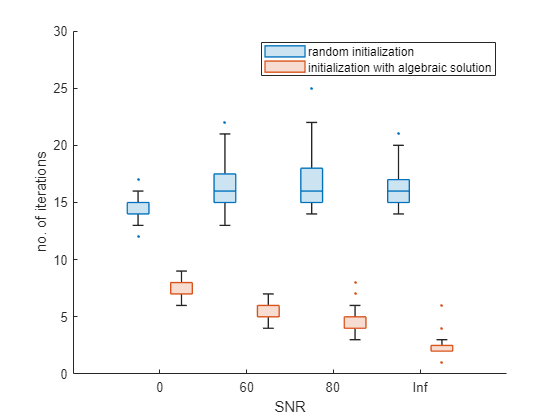

boxchart(categorical(exp_data.SNR),exp_data.iterations,'GroupByColor',exp_data.type,'MarkerStyle','.')
ylabel('no. of iterations')
xlabel('SNR')
%title('Iterations required for optimization function(noise on the coeffiecient tensor,\{2,3\} diag)')
legend('random initialization','initialization with algebraic solution')
legend
ylim([0,30])

figure
x = SNRS

x =      0    60    80   Inf


% plot(x,median(init_SNR_iters,2),'-o',x,median(rnd_SNR_iters,2),'-o')
plot(x,boxplot(init_SNR_iters'),x,boxchart(rnd_SNR_iters'))
%title('iterations required for optimization function(noise on the right-hand side b)')
legend('initialization with algebraic solution','random initialization')
xlabel('tensor size(n x n x n)')
ylabel('no. of iterations')

SNRS = [0,40,80,Inf];
iters = 100;

%% initialized exp_data %%
init_SNR_iters = [];
rnd_SNR_iters = [];
exp_data.iterations = [];
exp_data.type = [];
exp_data.SNR = ones(1,iters*2)*SNRS(1);
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(2)];
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(3)];
exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(4)];
% exp_data.SNR = [exp_data.SNR, ones(1,iters*2)*SNRS(5)];
options = struct;
options.TolFun = eps^2;
options.TolX = eps;
options.LargeScale = false;
%% -----------------   %%
for SNR=1:size(SNRS,2)
    init_iterations = [];
    rnd_iterations = [];
    for iter=1:iters
        dim = [20,20,20];
        T = zeros(dim);
        for i = 1:size(T,1)
            T(i,:,:) = diag(randi([-100,100],size(T,2),1));
        end

        x = randi([-100,100],dim(2),1);
    
        b = tmprod(T,{x.',x.'},[2,3]);
        b_noisy = noisy(b,SNRS(SNR));
        T_noisy = noisy(T,SNRS(SNR));
        T_noisy_dup = zeros(size(T_noisy));

        for k = 1:size(T,1)
            T_noisy_dup(k,:,:) = diag(diag(squeeze(T_noisy(k,:,:))));
        end

        xest = solve_part_diag(T_noisy_dup,b_noisy);
    
     
        U0 = {xest,xest};
        [U,output] = lscpd_nls(T_noisy,b_noisy,U0,options);
        init_iterations = [init_iterations,output.iterations];

        %%collecting data
        exp_data.iterations = [exp_data.iterations,output.iterations];
        exp_data.type = [exp_data.type,1];
        %%--------------%%

        U0 = cpd_rnd(dim(2:3),1);
        [U2,output2] = lscpd_nls(T_noisy,b_noisy,U0,options);

        %%collecting data
        rnd_iterations= [rnd_iterations,output2.iterations];
        exp_data.iterations = [exp_data.iterations,output2.iterations];
        exp_data.type = [exp_data.type,0];
        %%--------------%%
    end
    init_SNR_iters = [init_SNR_iters;init_iterations];
    rnd_SNR_iters = [rnd_SNR_iters;rnd_iterations];
end

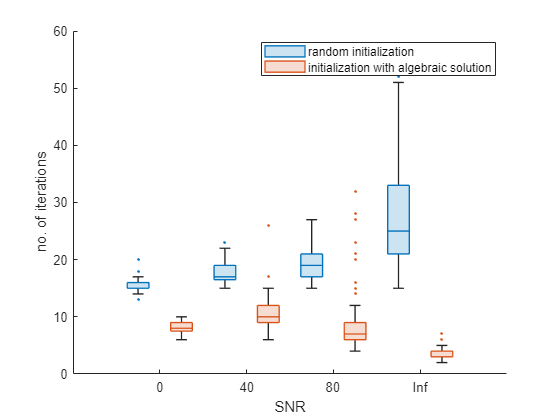

boxchart(categorical(exp_data.SNR),exp_data.iterations,'GroupByColor',exp_data.type,'MarkerStyle','.')
ylabel('no. of iterations')
xlabel('SNR')
%title('Iterations required for optimization function(noise on the coeffiecient tensor,\{2,3\} diag and right hand side b)')
legend('random initialization','initialization with algebraic solution')
legend
ylim([0,60])

Experiments for circular structure